# Модулятор

# Double Sideband Suppressed Carrier 

# (AM-DSB-SC)

### 1. Введение

Амплитудная модуляция с подавленной несущей выполняется с помощью умножения информационного сообщения на гармонический сигнал, который называют неcущей (carrier). Схема модулятора представлена ниже:

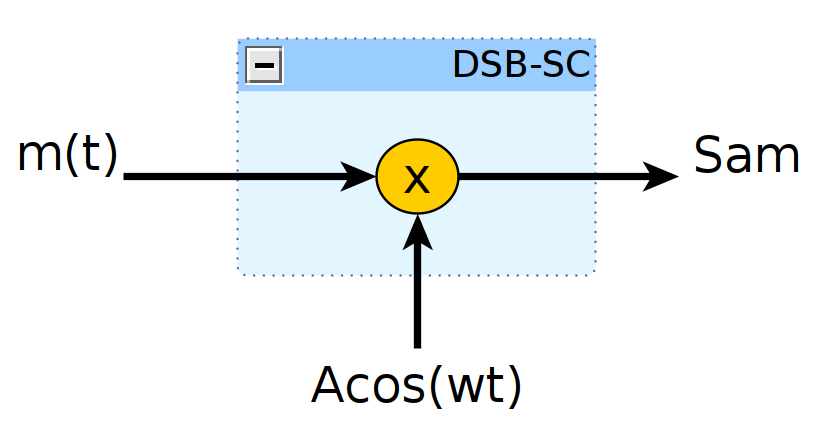

С помощью формул данный модулятор можно записать в следующем виде:

$s_{\textrm{am}} \left(t\right)=m\left(t\right)\cdot A_c \cos \left(2\pi f_c t\right)$,                                                                             (1)

где $m\left(t\right)$ - информационное сообщение, $A_c$ - амплитуда несущей, $f_c$ - частота несущей, $s_{\textrm{am}} \left(t\right)$ - модулированный сигнал.

Рассмотрим, что происходит в частотной области. Будем считать, что спектр информационного сообщения равен

$m\left(t\right)\iff M\left(f\right)$.

Несущая представляет из себя гармонический сигнал, спектор которого состоит из двух дельта-функций:

$A_c \cos \left(2\pi f_c t\right)\iff \frac{A_c }{2}\left\lbrack \delta \left(f+f_c \right)+\delta \left(f-f_c \right)\right\rbrack$.

Произведение сигналов во временной области соответствует свертке их спектров в частотной области. Свертка с дельта-функцей соответствует переносу спектра по частоте. Таким обзом, модулированный сигнал будет состоять из двух копий спектров информационного сообщения, сдвинутых на частоты $f_c$ и ${-f}_c$:

$m\left(t\right)\cdot A_c \cos \left(2\pi f_c t\right)\iff \frac{A_c }{2}M\left(f+f_c \right)+\frac{A_c }{2}M\left(f-f_c \right)$.                                                             (2)

Далее рассмотрим несколько частных случаев: однотональную модуляцию, модуляцию неколькими тонами и модуляцию аудиосигналом.

### 2. Однотональная модуляция

В случае однотональной модуляции информационное сообщение представляет из себя гармонический сигнал вида: 

$m\left(t\right)=A_m \cos \left(2\pi f_m t\right)$,

где $A_m$ - амплитуда тона, $f_m$ - частота в герцах. 

Подставим этот гармонический сингнал в формулу (1) и получим:

$s_{\textrm{am}} \left(t\right)=A_m \cos \left(2\pi f_m t\right)\cdot A_c \cos \left(2\pi f_c t\right)$.                                                                     (3) 

Ниже представлен скрипт для получения графика сигнала после однотональной модуляции:

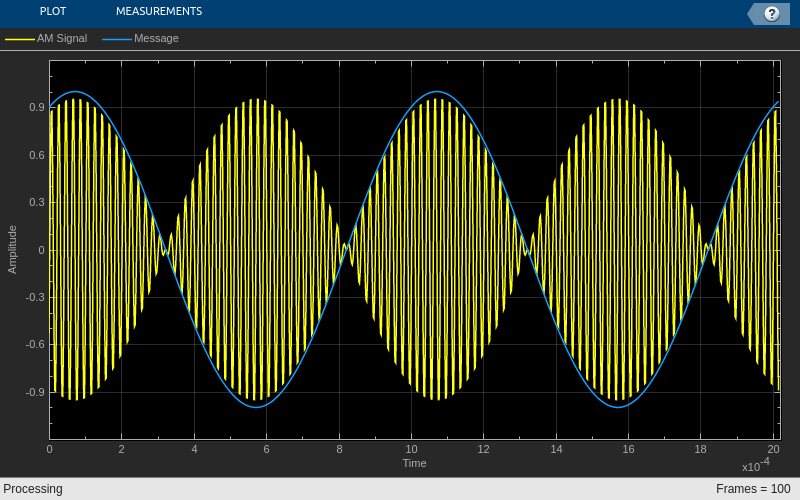

clc; clear; close all;

FrameSize = 1011;   % размер обрабатываемой за один раз пачки данных
Fs = 500e3;         % тактовая частота (Hz)

% генератор гармонических сигналов
% частота тона: 1 kHz
% частота несущей: 50 kHz
MessageAndCarrierGen = dsp.SineWave(...
    'SampleRate', Fs, ...
    'SamplesPerFrame', FrameSize, ...
    'Frequency', [50e3 1e3], ...
    'Amplitude', [1 1] ...
    );

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType', 'Line', ...
    'YLimits', [-1.2, 1.2], ...
    'SampleIncrement', 1/Fs, ...
    'XLabel', 'Time', ...
    'YLabel', 'Amplitude', ...
    'ChannelNames', {'AM Signal', 'Message'} ...
    );

% запуск симуляции
for i = 1:100
    % формирование тонального сигнала и несущей
    SineWaves = MessageAndCarrierGen();
    Carrier = SineWaves(:,1); 
    Message = SineWaves(:,2);

    % амплитудная модуляция
    AmSignal = Message.*Carrier;

    % вывод результатов на график
    Plotter([AmSignal, Message])

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.1)
end

Можно увидеть, что амплитуда несущей соответствует амплитуде информационного сообщения. Если информационное сообщение принимает отрицательное значение, то фаза несущей изменяется на $\pi$.

Теперь рассмотрим частотную область. Применив в формуле (3) правило произведения косинусов, преобразуем результат к следующему виду:

$s_{\textrm{am}} \left(t\right)=\frac{A_m A_c }{2}\left\lbrack \cos \left(2\pi \left(f_m +f_c \right)t\right)+\cos \left(2\pi \left(f_m -f_c \right)t\right)\right\rbrack$.

Такми образом, результат однотональной модуляции равен сумме двух гармонических сигналов, частоты которых равны $f_m +f_c$ и $f_m -f_c$ Гц. В частотной области это соответствует спектру:

$s_{\textrm{am}} \left(t\right)\iff \frac{A_m A_c }{4}\left\lbrack \delta \left(f+f_c +f_m \right)+\delta \left(f+f_c -f_m \right)+\delta \left(f-f_c +f_m \right)+\delta \left(f-f_c -f_m \right)\right\rbrack$.

Этот результат можно получить, если учесть формулу (2) и, что спектр информацонного сигнала равен: 

$A_m \cos \left(2\pi f_m t\right)\iff \frac{A_m }{2}\left\lbrack \delta \left(f+f_m \right)+\delta \left(f-f_m \right)\right\rbrack$.

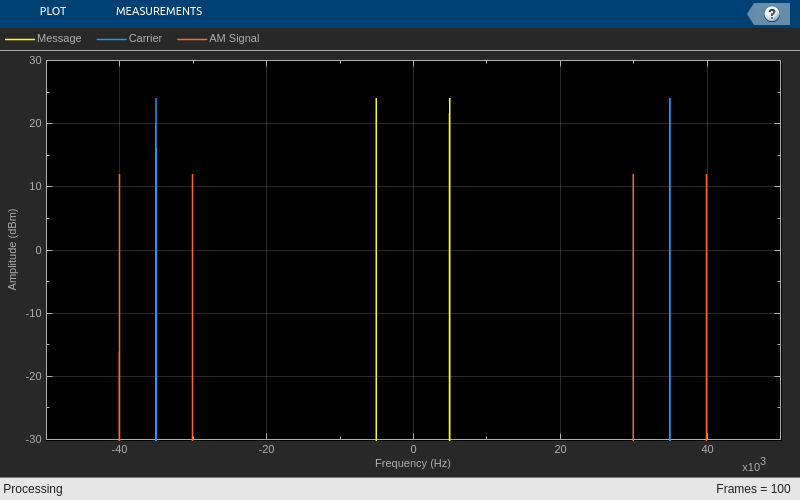

clc; clear; close all;

FrameSize = 5000;   % размер обрабатываемой за один раз пачки данных
Fs = 100e3;         % тактовая частота (Hz)

% генератор гармонических сигналов
% частота тона: 5 kHz
% частота несущей: 35 kHz
MessageAndCarrierGen = dsp.SineWave(...
    'SampleRate',Fs,...
    'SamplesPerFrame',FrameSize,...
    'Frequency',[35e3 5e3],...
    'Amplitude',[1 1] ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm', ...
    'FrequencyRange', 'centered', ...
    'SampleRate', Fs ...
    );

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -Fs/2, ...
    'YLimits', [-30, 30], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'Message', 'Carrier', 'AM Signal'}, ...
    'SampleIncrement', Fs/FrameSize ...
    );

% запуск симуляции
for i = 1:100
    % формирование тонального сигнала и несущей
    SineWaves = MessageAndCarrierGen();
    Carrier = SineWaves(:,1); 
    Message = SineWaves(:,2);

    % амплитудная модуляция
    AmSignal = Message.*Carrier;

    % вычисление спектров
    Spectrums = SpecEstimator([Message, Carrier, AmSignal]);
    
    % вывод результатов на график
    Plotter(Spectrums)
    
    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.1)
end

На графике представлен спектр информационного сигнала (желтый) и спектр несущей (синий). Эти сигналы гармонические, поэтому им соответствуют гармоники на частотах $f_m$ и $f_c$ соответственно. Спектр модулированного сигнала для однотонального случая (красный) состоит их четырех дельта-функций.

### 3. Модуляция несколькими тонами

Разобравшись с однотональной модуляцией, легко распространить результаты на случай модуляции несколькими тонами. Пусть информационный сигнал представляет из себя сумму гармонических сигналов:

$m\left(t\right)=\sum_{i=1}^N A_i \cos \left(2\pi f_i t\right)$,

где $A_i$ - амплитада i-ой гармоники, $f_i$ - частота i-ой гармоники, $N$ - число гармоник.

В случае, если в модуляции учавствуют три тона, график сигнала будет иметь вид:

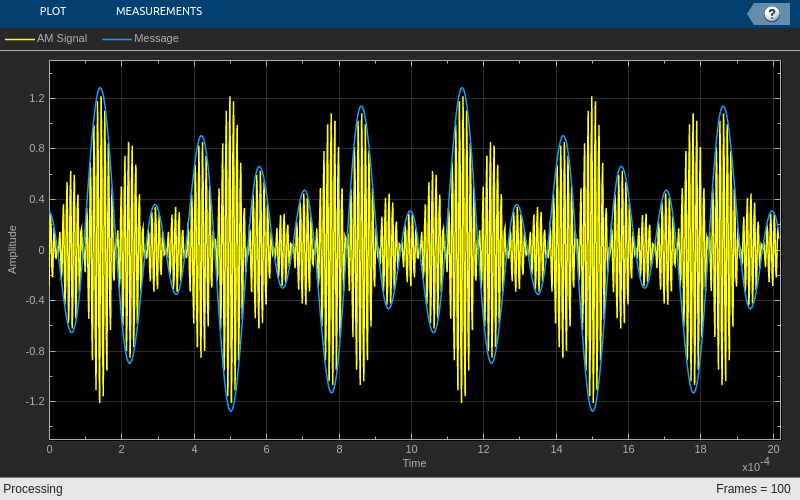

clc; clear; close all;

FrameSize = 1011;   % размер обрабатываемой за один раз пачки данных
Fs = 500e3;         % тактовая частота (Hz)

% генератор информационного сигнала из трех тонов
% частота тонов: 1, 4 и 7 kHz
% амплитуды тонов: 0.1, 0.5 и 0.7
Message = dsp.SineWave(...
    'SampleRate', Fs, ...
    'SamplesPerFrame', FrameSize, ...
    'Frequency', [1e3 4e3 7e3], ...
    'Amplitude', [0.1 0.5 0.7] ...
    );

% генератор несущей
% частота несущей: 100 kHz
Carrier = dsp.SineWave(...
    'SampleRate', Fs, ...
    'SamplesPerFrame', FrameSize, ...
    'Frequency', 100e3, ...
    'Amplitude', 1 ...
    );

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'YLimits', [-1.5, 1.5], ...
    'SampleIncrement', 1/Fs, ...
    'XLabel', 'Time', ...
    'YLabel', 'Amplitude', ...
    'ChannelNames', {'AM Signal', 'Message'} ...
    );

% запуск симуляции
for i = 1:100
    % формирование информационного сигнала
    MessageData = Message();
    MessageData = MessageData(:,1) + MessageData(:,2) + MessageData(:,3);
    
    % формирование несущей
    CarrierData = Carrier();

    % амплитудная модуляция
    AmSignal = MessageData .* CarrierData; 

    % вывод результатов на график
    Plotter([AmSignal, MessageData])

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.1)
end

Рассмотрим, что происходит в частотной области. В случае модуляции несколькими тонами модулированный сигнал примет следующий вид:  

$s_{\textrm{am}} \left(t\right)=\sum_{i=1}^N A_i \cos \left(2\pi f_i t\right)\cdot A_c \cos \left(2\pi f_c t\right)=\frac{A_c }{2}\sum_{i=1}^N A_i \left\lbrack \cos \left(2\pi \left(f_i +f_c \right)t\right)+\cos \left(2\pi \left(f_i -f_c \right)t\right)\right\rbrack$.

То есть после модуляции каждому тону будут соответстовать две гармоники на частотах $f_i +f_c$ и $f_i -f_c$. Можно сказать по другому: каждый отдельный тон информационного сигнала будет сдвинут по частоте на $f_c$. Построим спектры сигналов для случая модуляции тремя тонами.

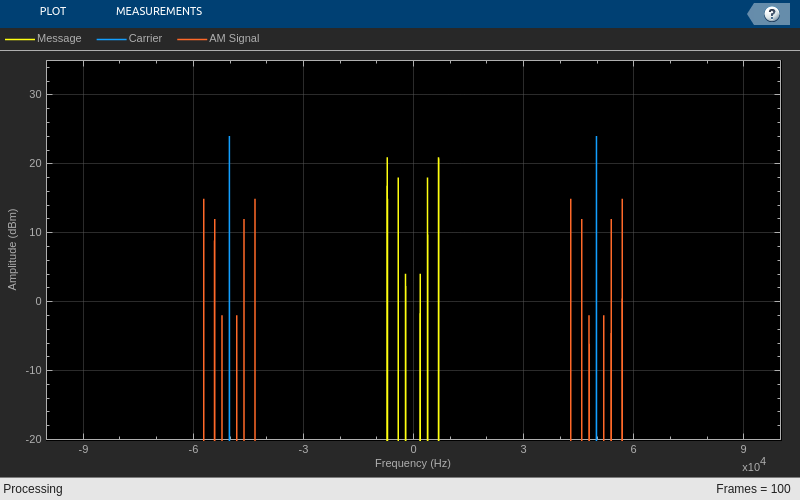

clc; clear; close all;

FrameSize = 5000;   % размер обрабатываемой за один раз пачки данных
Fs = 200e3;         % тактовая частота (Hz)

% генератор информационного сигнала из трех тонов
% частота тонов: 2, 4 и 7 kHz
% амплитуды тонов: 0.1, 0.5 и 0.7
Message = dsp.SineWave(...
    'SampleRate', Fs,...
    'SamplesPerFrame', FrameSize,...
    'Frequency', [2e3 4e3 7e3],...
    'Amplitude', [0.1 0.5 0.7]);

% генератор несущей
% частота несущей: 50 kHz
Carrier = dsp.SineWave(...
    'SampleRate', Fs,...
    'SamplesPerFrame', FrameSize,...
    'Frequency', 50e3,...
    'Amplitude', 1 ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',Fs ...
    );

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -Fs/2, ...
    'YLimits', [-20, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'Message', 'Carrier', 'AM Signal'}, ...
    'SampleIncrement', Fs/FrameSize ...
    );

% запуск симуляции
for i = 1:100
    % формирование информационного сигнала
    MessageData = Message();
    MessageData = MessageData(:,1) + MessageData(:,2) + MessageData(:,3);
    
    % формирование несущей
    CarrierData = Carrier();

    % амплитудная модуляция
    AmSignal = MessageData .* CarrierData; 

    % вычисление спектров
    SpectrumData = SpecEstimator([MessageData, CarrierData, AmSignal]);
    
    % вывод результатов на график
    Plotter(SpectrumData)

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.1)
end

Можно увидеть, что спектр модулированного сигнала (красный) соответсвует спектру информационного сообщения (желтый), сдвинутому на частоту несущей (синий).

### 4. Модуляция звуковым сигналом

Рассмотрим, как будет выглядеть спектр сигнала после модуляции, если информационное сообщение является аудиосигналом. В файле Audio_Source.wav записано звуковое сообщение с частотой дискретизации 44.1 kHz. Частота несущей будет равна 60 kHz. Чтобы избежать наложения спектров, выберем итоговую частоту дискретизации модулированного сигнала в 5 раз больше частоты аудиосигнала, то есть 5 * 44.1 kHz. Это потребует провести интерполяцию для увеличения частоты дискретизации информационного сообщения.

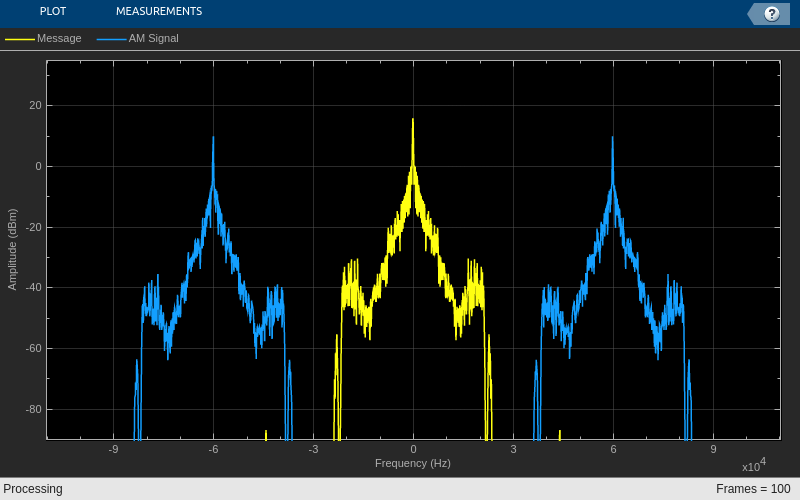

clc; clear; close all;

AudioFrameSize = 1000;  % количество отсчетов аудиофайла, получаемых за один раз
FramesNumber = 100;     % число обрабатываемых пачек данных
RateRatio = 5;          % коэффициент увеличения частоты дискретизации

% объект для считываения отсчетов аудиофайла
AudioReader = dsp.AudioFileReader(...
    'wav/Audio_Source.wav', ...
    'SamplesPerFrame',AudioFrameSize...
    );

% дополнительные расчеты
AudioFs = AudioReader.SampleRate;               % получаем частоту дискретизации аудиосообщения
SignalFs = AudioFs * RateRatio;                 % частота дискретизации модулированного сигнала
SignalFrameSize = AudioFrameSize * RateRatio;   % количество отсчетов Ам-сигнала, получаемых за один раз

% генератор несущей с частотой 60 kHz
Carrier = dsp.SineWave(...
    'SampleRate', SignalFs,...
    'SamplesPerFrame', SignalFrameSize,...
    'Frequency', 60e3,...
    'Amplitude', 1);

% интерполятор 
Upsampler = dsp.SampleRateConverter(...
    'Bandwidth', 40e3, ...
    'InputSampleRate',AudioFs, ...
    'OutputSampleRate', SignalFs ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',SignalFs);

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -SignalFs/2, ...
    'YLimits', [-90, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'Message', 'AM Signal'}, ...
    'SampleIncrement', SignalFs/SignalFrameSize ...
    );

% запуск симуляции
for i = 1:FramesNumber
    % считывание отсчетов аудиосообщения и выделение одного канала из
    % стерео сигнала
    AudioData = AudioReader();
    AudioData = AudioData(:,1);

    % увеличение частоты дискретизации аудиосообщения
    MessageData = Upsampler(AudioData);

    % амплитудная модуляция
    AmSignal = MessageData .* Carrier();

    % вычисление спектров
    SpectrumData = SpecEstimator([MessageData, AmSignal]);

    % вывод результатов на график
    Plotter(SpectrumData)

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.1)
end

Можно увидеть, что спектр информационного сообщения перенесен на частоту несущей.

### 5. Готовые решения Matlab

В среде Matlab есть готовая функция для выполения амплитудной модуляции: ammod(). Проверим ее работу. Функция принимает на вход информационный сигнал, частоту несущей, частоту дискретизации и начальную фазу несущей. Основная часть скрипта совпадает со скриптом из предыдущего раздела.

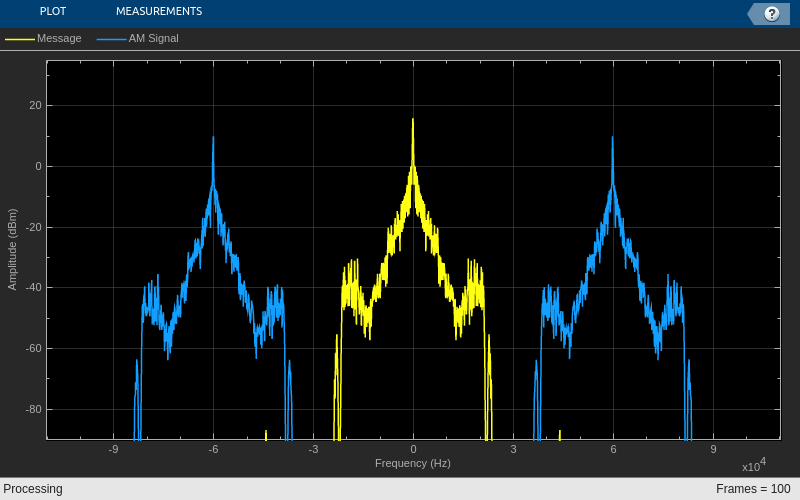

clc; clear; close all;

AudioFrameSize = 1000;  % количество отсчетов аудиофайла, получаемых за один раз
FramesNumber = 100;     % число обрабатываемых пачек данных
RateRatio = 5;          % коэффициент увеличения частоты дискретизации

CarrierPhase = 0;       % начальная фаза несущей 
CarrierFreq = 60e3;     % частота несущей

% объект для считываения отсчетов аудиофайла
AudioReader = dsp.AudioFileReader(...
    'wav/Audio_Source.wav', ...
    'SamplesPerFrame',AudioFrameSize...
    );

% дополнительные расчеты
AudioFs = AudioReader.SampleRate;               % получаем частоту дискретизации аудиосообщения
SignalFs = AudioFs * RateRatio;                 % частота дискретизации модулированного сигнала
SignalFrameSize = AudioFrameSize * RateRatio;   % количество отсчетов Ам-сигнала, получаемых за один раз

% интерполятор 
Upsampler = dsp.SampleRateConverter(...
    'Bandwidth', 40e3, ...
    'InputSampleRate',AudioFs, ...
    'OutputSampleRate', SignalFs ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',SignalFs);

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -SignalFs/2, ...
    'YLimits', [-90, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'Message', 'AM Signal'}, ...
    'SampleIncrement', SignalFs/SignalFrameSize ...
    );

% запуск симуляции
for i = 1:FramesNumber
    % считывание отсчетов аудиосообщения и выделение одного канала из
    % стерео сигнала
    AudioData = AudioReader();
    AudioData = AudioData(:,1);

    % увеличение частоты дискретизации аудиосообщения
    MessageData = Upsampler(AudioData);

    % амплитудная модуляция
    AmSignal = ammod(MessageData, CarrierFreq, SignalFs, CarrierPhase);

    % вычисление новой фазы нусущей
    CarrierPhase = CarrierPhase + 2*pi*CarrierFreq/SignalFs*SignalFrameSize;

    % вычисление спектров
    SpectrumData = SpecEstimator([MessageData, AmSignal]);

    % вывод результатов на график
    Plotter(SpectrumData)

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.1)
end

Спектр модулированного сигнала совпадает со спектром из предыдущего пункта.

### 6. Модуляция DSB-SC в Similink

В файле DSB_SC_Transmitter.slx представлена Simulink-модель модуляции аудиосообщением. Как и в предыдущих скриптах в файле Audio_Source.wav записано звуковое сообщение с частотой дискретизации 44.1 kHz. Частота несущей равна 60 kHz. Перед модуляцией частота дискретизации увеличивается в 5 раз. Блок DSBSC AM принимает и выдает данные только по одному отсчету. Поэтому до этого блока данные преобразуются из вектора в отсчеты (Unbuffer), а после него опять собираются в вектор (Buffer). Схема модели и спектры сигналов представлены ниже:

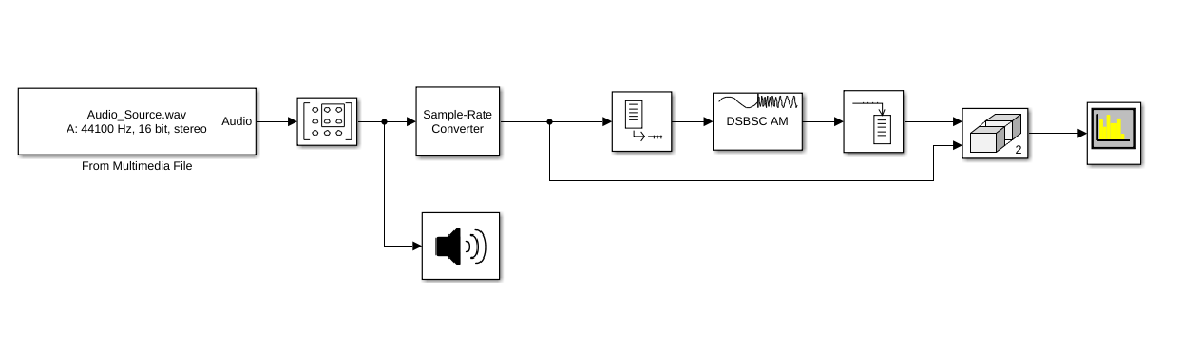

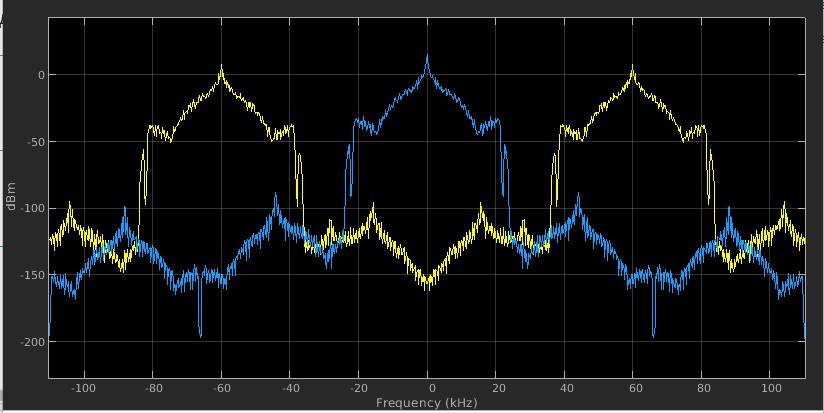

### 7. Преимущества и недостатки DSB-SC

####     Преимущества:

- простота модулятора;

- модуляция эффективна с точки зрения мощности, так как несущая не передается.

####     Недостатки:

- если информационное сообщение изменяет знак, то возможна только когерентная демодуляция;

- несущая не передается, ее нужно восстанавливать из сигнала, это усложняет демодулятор;

- полоса модулированного сигнала в 2 раза больше полосы информационного сообщения.

### Ссылки:

- [https://en.wikipedia.org/wiki/Double-sideband_suppressed-carrier_transmission](https://en.wikipedia.org/wiki/Double-sideband_suppressed-carrier_transmission)

- [https://www.javatpoint.com/dsbsc-double-sideband-suppress-carrier](https://www.javatpoint.com/dsbsc-double-sideband-suppress-carrier)

- [https://electronicscoach.com/double-sideband-suppressed-carrier-modulation.html](https://electronicscoach.com/double-sideband-suppressed-carrier-modulation.html)

- [https://user.eng.umd.edu/~tretter/commlab/c6713slides/ch6.pdf](https://user.eng.umd.edu/~tretter/commlab/c6713slides/ch6.pdf)

### Литература:

- B. P. Lathi Modern Digital and Analog Communication Systems

- R. Stewart, K. Barlee, D. Atkinson, L. Crockett Software Defined Radio using MATLAB® & Simulink and the RTL-SDR